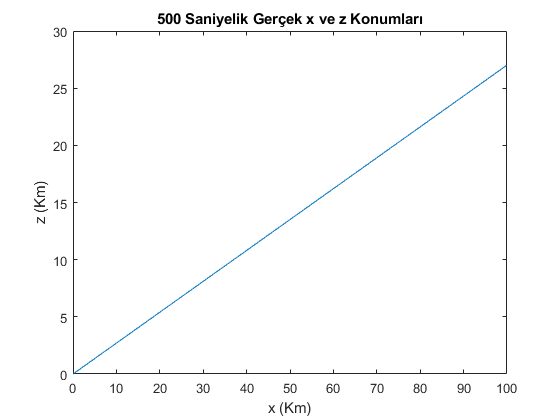

n=12;
v=195+n; %m/s
y0= 6355000; %m yükseklik-sabit
x0=0;
z0=0;
t_delta=1;
gama=(15+n/100)*pi/180;
adim=500;
x=x0:v*t_delta*cos(gama):v*t_delta*cos(gama)*adim;
z=z0:v*t_delta*sin(gama):v*t_delta*sin(gama)*adim;
y=zeros(1,adim+1)+3000;

figure(1)
h1=plot(x/1000,z/1000);
title('500 Saniyelik Gerçek x ve z Konumları');
xlabel('x (Km)');
ylabel('z (Km)');


m1=(z(100)-z(99))/(x(100)-x(99));
m2=-1/m1;

st1=[50000 , 13500  , 0];
st2=[62847.3 , -34152.7  , 0];
st3=[37152.7  , 61821.3 , 0];
st4=[0 0 0];


%Her bir istasyon ile uçak arasında olan mesafe
D1=sqrt( (st1(1)-x).^2 + (st1(2)-z).^2 + (st1(3)-y).^2 );
D2=sqrt( (st2(1)-x).^2 + (st2(2)-z).^2 + (st2(3)-y).^2 );
D3=sqrt( (st3(1)-x).^2 + (st3(2)-z).^2 + (st3(3)-y).^2 );
D4=sqrt( (st4(1)-x).^2 + (st4(2)-z).^2 + (st4(3)-y).^2 );

%Her bir istasyonun 0,0,0 noktasına olan mesafesi
l1 = sqrt(st1(1)^2 + st1(2)^2 + st1(3)^2 );
l2 = sqrt(st2(1)^2 + st2(2)^2 + st2(3)^2 );
l3 = sqrt(st3(1)^2 + st3(2)^2 + st3(3)^2 );
l4 = sqrt(st4(1)^2 + st4(2)^2 + st4(3)^2 );


%c1 = [St1(1)-St2(1), St1(2)-St2(2), St1(3)-St2(3)]
%c2 = [St1(1)-St3(1), St1(2)-St3(2), St1(3)-St3(3)]
%c3 = [St2(1)-St3(1), St2(2)-St3(2), St2(3)-St3(3)]

c1=0.5* (D2.^2 - D1.^2 + l1^2 - l2^2);
c2=0.5* (D3.^2 - D1.^2 + l1^2 - l3^2);
c3=0.5* (D3.^2 - D2.^2 + l2^2 - l3^2);

sigma_D=10; %metre
bias=10+n; % bias
% D Uçağa kadar olan mesafe
% Delta_D = Uçaktan iki çeşitli antene kadar olan mesafeler farkı
% Uçaktan iki çeşitli antene kadar olan mesafeler toplamı
% Belirli antene göre açıların doğrultman kosinüsleri
% Uçağın alfa:azimut ve beta: konum açılarını
% Kayıt olan parametrelerin değişme hızleri

DZ1 = D1 + bias + sigma_D*randn(1,501);
DZ2 = D2 + bias + sigma_D*randn(1,501);
DZ3 = D3 + bias + sigma_D*randn(1,501);
DZ4 = D4 + bias + sigma_D*randn(1,501);

e1=( c1.*(st2(2)-st3(2)) - c3.*(st1(2)-st2(2)) ) / ( (st1(1)-st2(1)).*(st2(2) -st3(2)) - (st2(1)-st3(1)).*( st1(2)-st2(2))   );

e2=( c1.*(st1(1)-st3(1)) - c2.*(st1(1)-st2(1)) ) / ( (st1(1)-st3(1)).*(st1(2) -st2(2)) - (st1(1)-st2(1)).*( st1(2)-st3(2))   );

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%


a= ( (st1(3)-st2(3))*(st2(2)-st3(2)) - (st2(3)-st3(3))*(st1(2)-st2(2)) ) / ( (st1(1)-st2(1))*(st2(2)-st3(2)) - (st2(1)-st3(1))*(st1(2)-st2(2)) );

b= ( (st1(3)-st2(3))*(st1(1)-st3(1)) - (st1(3)-st3(3))*(st1(1)-st2(1)) ) / ( (st1(1)-st3(1))*(st1(2)-st2(2)) - (st1(1)-st2(1))*(st1(2)-st3(2)) );

p_y2=ones(1,501)*(a^2 + b^2 + 1) ;
p_y=2*( st1(1)*a - st1(3) + st1(2)*b - a.*e1 - b.*e2) ;
p_c= -1*(D1(1)^2 - l1^2 - e1.^2 + 2*st1(1).*e1 - e2.^2 + 2*st1(2).*e2) ;  

polynom=[p_y2',p_y', p_c'];

% rts{1,501};
% figure(6)
% for i=1:501
%     rts{1,i}=roots((polynom(i,1).coeff));
%     plot(i,(rts{i,1}))
%     hold on
% end


y1= sqrt( DZ1.^2 - l1^2 - e1.^2 + 2*st1(1).*e1 + 2*st1(2).*e2 -e2.^2 );
disc=[polynom(:,2).^2-4*polynom(:,1).*polynom(:,3), polynom(:,2).^2 + 4*polynom(:,1).*polynom(:,3)]

disc = 	1.0e+10 *

    0.0036   -0.0036
    0.0122   -0.0122
    0.0207   -0.0207
    0.0292   -0.0292
    0.0376   -0.0376
    0.0461   -0.0461
    0.0544   -0.0544
    0.0628   -0.0628
    0.0711   -0.0711
    0.0794   -0.0794




x1=e1-a.*y1;
z1=e2-b.*y1;